# ECMOR-2022

## Control blocks

 

slider =100;

dropdown = slider;

check = true;

edit = 0.618 * check * dropdown;



## Introduction

bound = [0,1];

genK = @(N) exp(genField(N+1, log(1), log(2))); % non-uniform
calcG = @(u) [1 + 0.5 * u.^2, u];

genBC = @(N) genField(N+2, 0, 1); % initial and boundary

### FOM

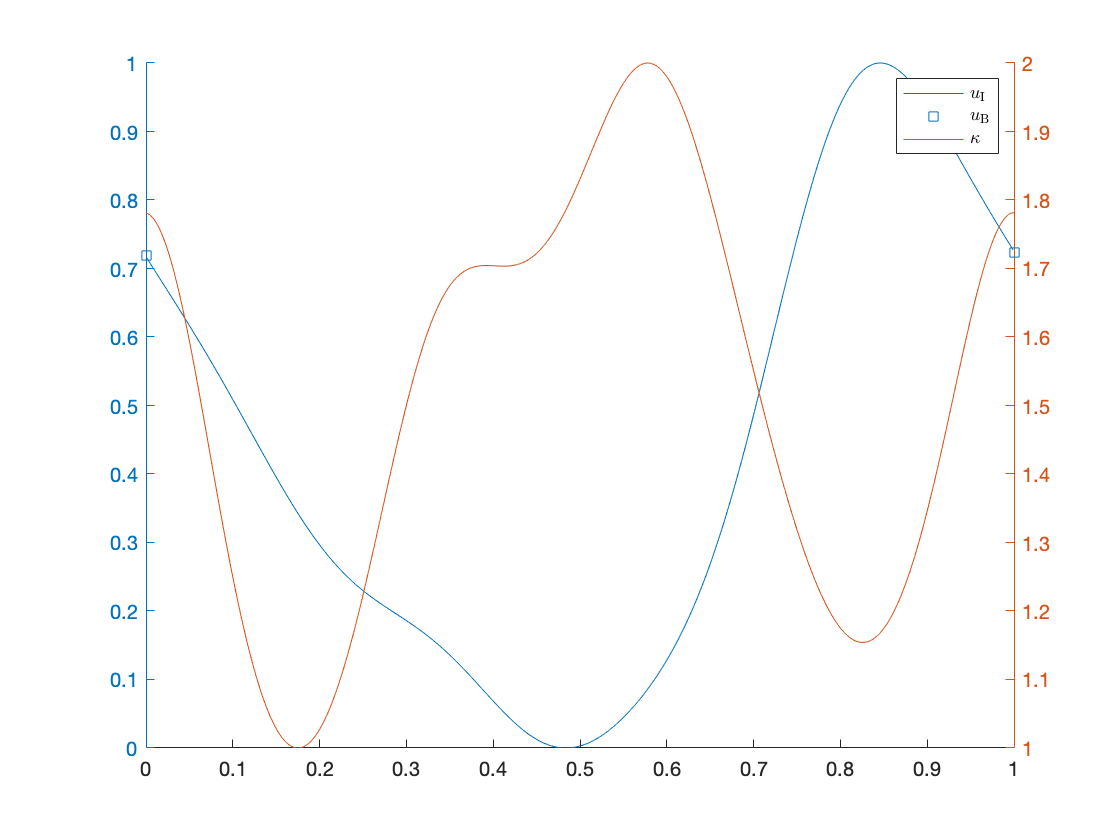

 
Nx = 500;
dx = 1/Nx;

K = genK(Nx);
U0 = genBC(Nx);

links = linspace(0,1,Nx+1);
cells = linspace(dx/2,1-dx/2,Nx);

clf;
hold on;
    yyaxis left;
        plot(cells,U0(2:end-1));
        plot(bound,[U0(1),U0(end)],'s');

    yyaxis right;
        plot(links,K);  
        
    xlim(bound);
    legend({'$u_\mathrm{I}$','$u_\mathrm{B}$','$\kappa$'},'interpreter','latex')
hold off;

### ROM-I

### ROM-II

### Generalizing ability

#### High

#### Low

## Method 1

### POD basis for different x_q

### Domain decomposition and mapping

### Zero-order approach

### Domain-wise POD performance